load CrackData.mat
crackData

crackData = 200×4 table
    NumRegions    Area    MaxWidth     fileName  
    __________    ____    ________    ___________

        2         2461     17.889     "00001.jpg"
        2         2125     17.889     "00002.jpg"
        2         2417         16     "00003.jpg"
        1         2438     14.142     "00004.jpg"
        4         1479     18.439     "00005.jpg"
        1         2356         14     "00006.jpg"
        1         2926     18.974     "00007.jpg"
        1         2573     15.232     "00008.jpg"
        2         1861     14.142     "00009.jpg"
        2         2663     17.088     "00010.jpg"
        1         3149     23.409     "00011.jpg"
        1         2722     18.974     "00012.jpg"
        2         1221      14.56     "00013.jpg"
        1         3050      25.06     "00014.jpg"
        1         2346         14     "00015.jpg"
        1         2740      14.56     "00016.jpg"


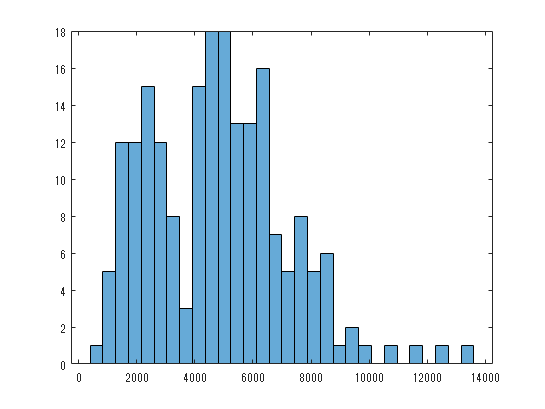

histogram(crackData.Area,30)

cutoffArea = 4000;
crackData.Risk = discretize(crackData.Area,[0,cutoffArea,inf],"categorical",["Mild","Severe"]);
% montage("../../Data/Data/Concrete Crack Images/" + crackData.fileName(crackData.Risk == "Severe"))
dsSevere = imageDatastore("../../Data/Data/Concrete Crack Images/" + crackData.fileName(crackData.Risk == "Severe"));

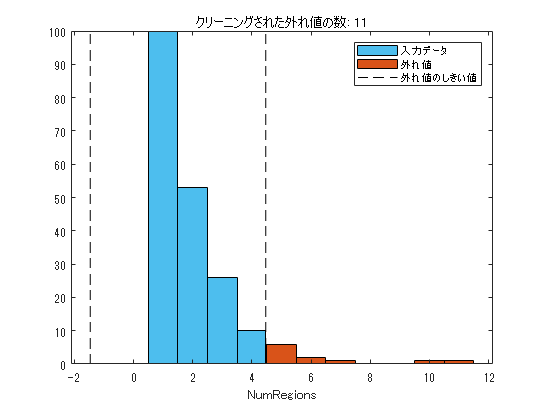

% 外れ値の削除
[newTable,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(crackData,...
    "ThresholdFactor",4,"DataVariables","NumRegions");

% 結果の表示
figure
[~,binEdges] = histcounts(crackData.NumRegions);
binEdges = unique([binEdges thresholdLow.NumRegions thresholdHigh.NumRegions]);
binEdges = binEdges(isfinite(binEdges));
histogram(crackData.NumRegions,"BinEdges",binEdges,...
    "FaceColor",[77 190 238]/255,"FaceAlpha",1,"DisplayName","入力データ")
hold on

% 外れ値のプロット
histogram(crackData.NumRegions(outlierIndices),"BinEdges",binEdges,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","外れ値")

% 外れ値のしきい値のプロット
plot([thresholdLow.NumRegions*[1 1] NaN thresholdHigh.NumRegions*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","外れ値のしきい値")

hold off
title("クリーニングされた外れ値の数: " + nnz(outlierIndices))
legend
xlabel("NumRegions")

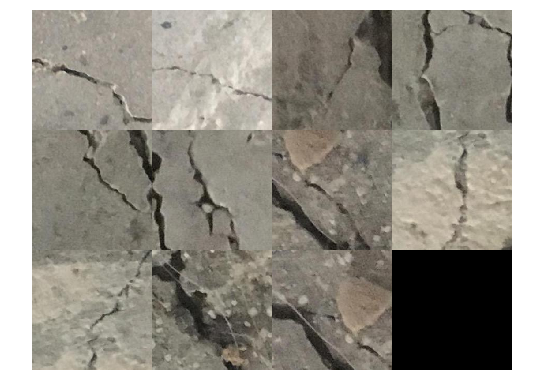

clear thresholdLow thresholdHigh binEdges
outlierImages = crackData.fileName(outlierIndices);
montage("../../Data/Data/Concrete Crack Images/" + outlierImages, "BorderSize",1);

clear
clc

load CrackData.mat
cutoffArea = 4000;
crackData.Risk = discretize(crackData.Area,[0,cutoffArea,inf],"categorical",["Mild","Severe"]);

crackData.MaxWidth = crackData.MaxWidth*0.5;
crackData.Area = crackData.Area*0.5*0.5;
mildMeanWidth = mean(crackData.MaxWidth(crackData.Risk=="Mild"))

mildMeanWidth = single
0.0169

severeMeanWidth = mean(crackData.MaxWidth(crackData.Risk=="Severe"))

severeMeanWidth = single
0.0369

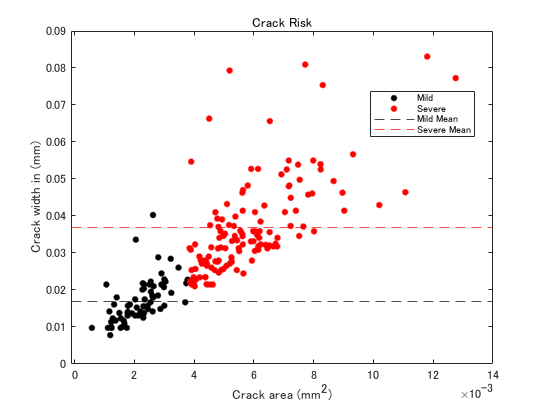

gscatter(crackData.Area,crackData.MaxWidth,crackData.Risk,"kr")
yline(mildMeanWidth,"k--","DisplayName","Mild Mean")
yline(severeMeanWidth,"r--","DisplayName","Severe Mean")
title("Crack Risk")
xlabel("Crack area (mm^2)")
ylabel("Crack width in (mm)")

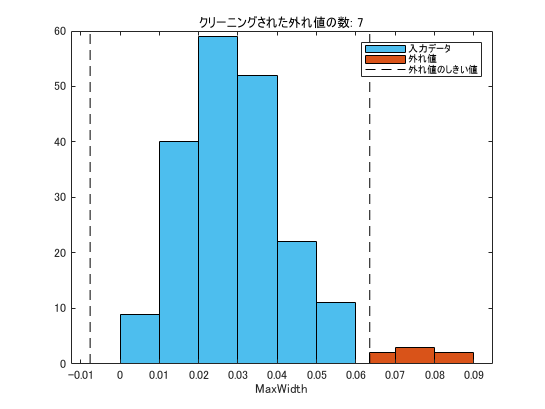

% 外れ値の削除
[newTable2,outlierIndices2,~,thresholdLow2,thresholdHigh2] = rmoutliers(crackData,...
    "DataVariables","MaxWidth");

% 結果の表示
figure
[~,binEdges2] = histcounts(crackData.MaxWidth);
binEdges2 = unique([binEdges2 thresholdLow2.MaxWidth thresholdHigh2.MaxWidth]);
binEdges2 = binEdges2(isfinite(binEdges2));
histogram(crackData.MaxWidth,"BinEdges",binEdges2,"FaceColor",[77 190 238]/255,...
    "FaceAlpha",1,"DisplayName","入力データ")
hold on

% 外れ値のプロット
histogram(crackData.MaxWidth(outlierIndices2),"BinEdges",binEdges2,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","外れ値")

% 外れ値のしきい値のプロット
plot([thresholdLow2.MaxWidth*[1 1] NaN thresholdHigh2.MaxWidth*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","外れ値のしきい値")

hold off
title("クリーニングされた外れ値の数: " + nnz(outlierIndices2))
legend
xlabel("MaxWidth")

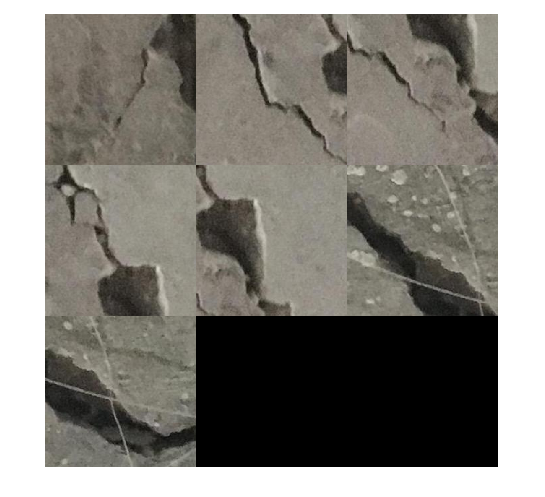

clear thresholdLow2 thresholdHigh2 binEdges2
montage("../../Data/Data/Concrete Crack Images/" + crackData.fileName(outlierIndices2))

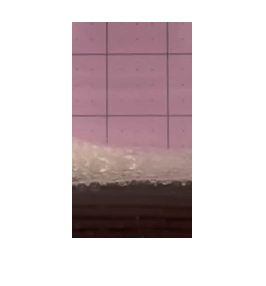

v = VideoReader("../../data/Data/MathWorks Images/liquidVideo.mp4");
img = read(v,92);
imshow(img)

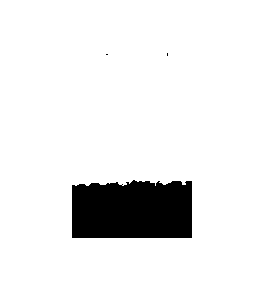

bw = imbinarize(imgGr);
imshow(bw)

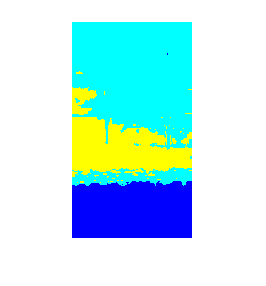

% thresh = imquantize(bw,2);
thresh = multithresh(imgGr,2);
levels = imquantize(imgGr,thresh);
imshow(label2rgb(levels))